# **Generalized chi-square distribution** · Getting started

The generalized chi-square variable is a quadratic form of a normal variable, or equivalently, a linear sum of independent non-central chi-square variables and a normal variable.

For more features and documentation, type:

doc gx2stat
doc gx2rnd
doc gx2cdf
doc gx2cdf_davies
doc gx2cdf_imhof
doc gx2cdf_ruben
doc gx2pdf
doc gx2inv
doc gx2_params_norm_quad 

If you use this toolbox, please cite: [A method to integrate and classify normal distributions](https://arxiv.org/abs/2012.14331).

Bugs/questions/comments to abhranil.das@utexas.edu.

Abhranil Das, Center for Perceptual Systems, University of Texas at Austin

## Calculate mean and variance

% gx2 parameters
lambda=[1 -10 2];
m=[1 2 3];
delta=[2 3 7];
sigma=5;
c=10;

[mu,v]=gx2stat(lambda,m,delta,sigma,c)

mu = -17

v = 1771

## Generate random samples

r=gx2rnd(lambda,m,delta,sigma,c,[1 1e4]);

## Calculate pdf and cdf

x=[10 25];
f=gx2pdf(x,lambda,m,delta,sigma,c)

f =     0.0121    0.0088


p=gx2cdf(x,lambda,m,delta,sigma,c,'AbsTol',0,'RelTol',1e-4)

p =     0.7150    0.8790


### Plot pdf and sample histogram

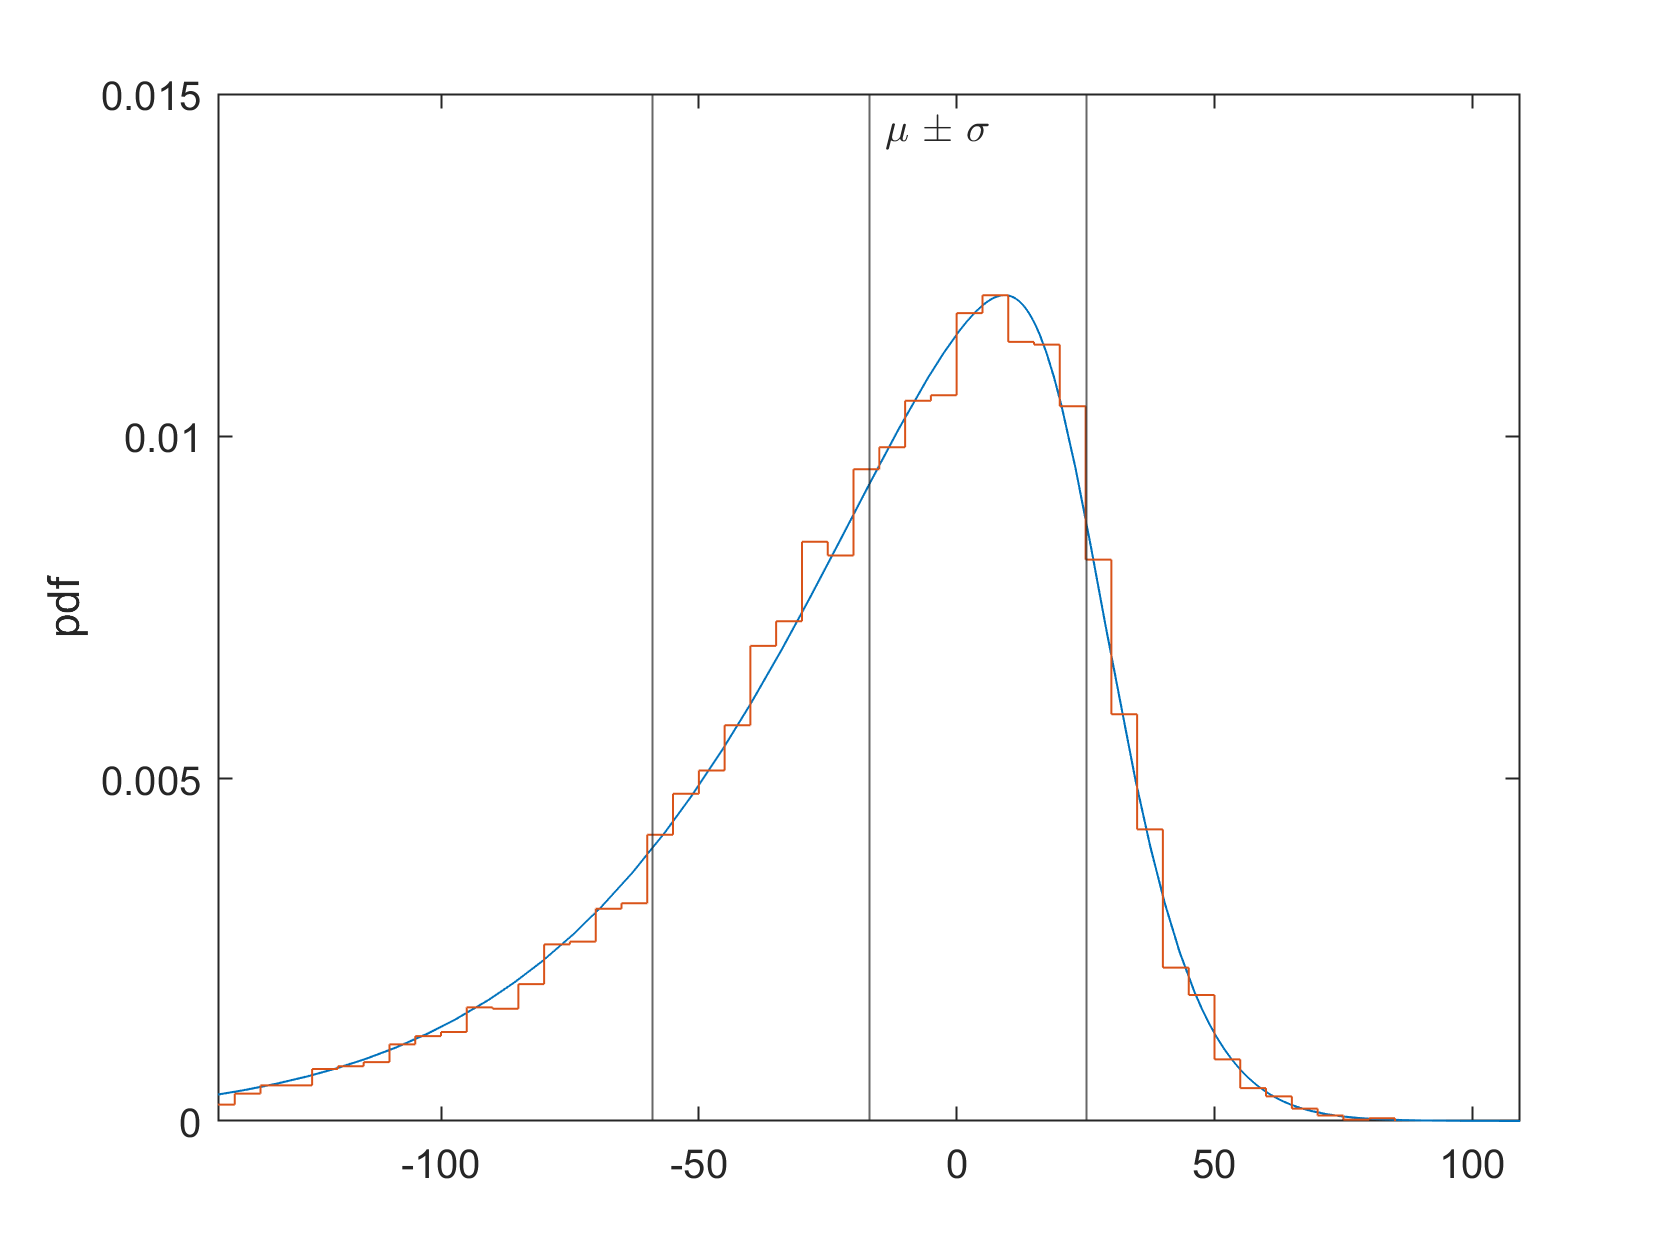

fplot(@(x) gx2pdf(x,lambda,m,delta,sigma,c))
hold on; histogram(r,'normalization','pdf','displaystyle','stairs')
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-3*sqrt(v),mu+3*sqrt(v)]); ylim([0 .015]); ylabel 'pdf'

### Plot cdf

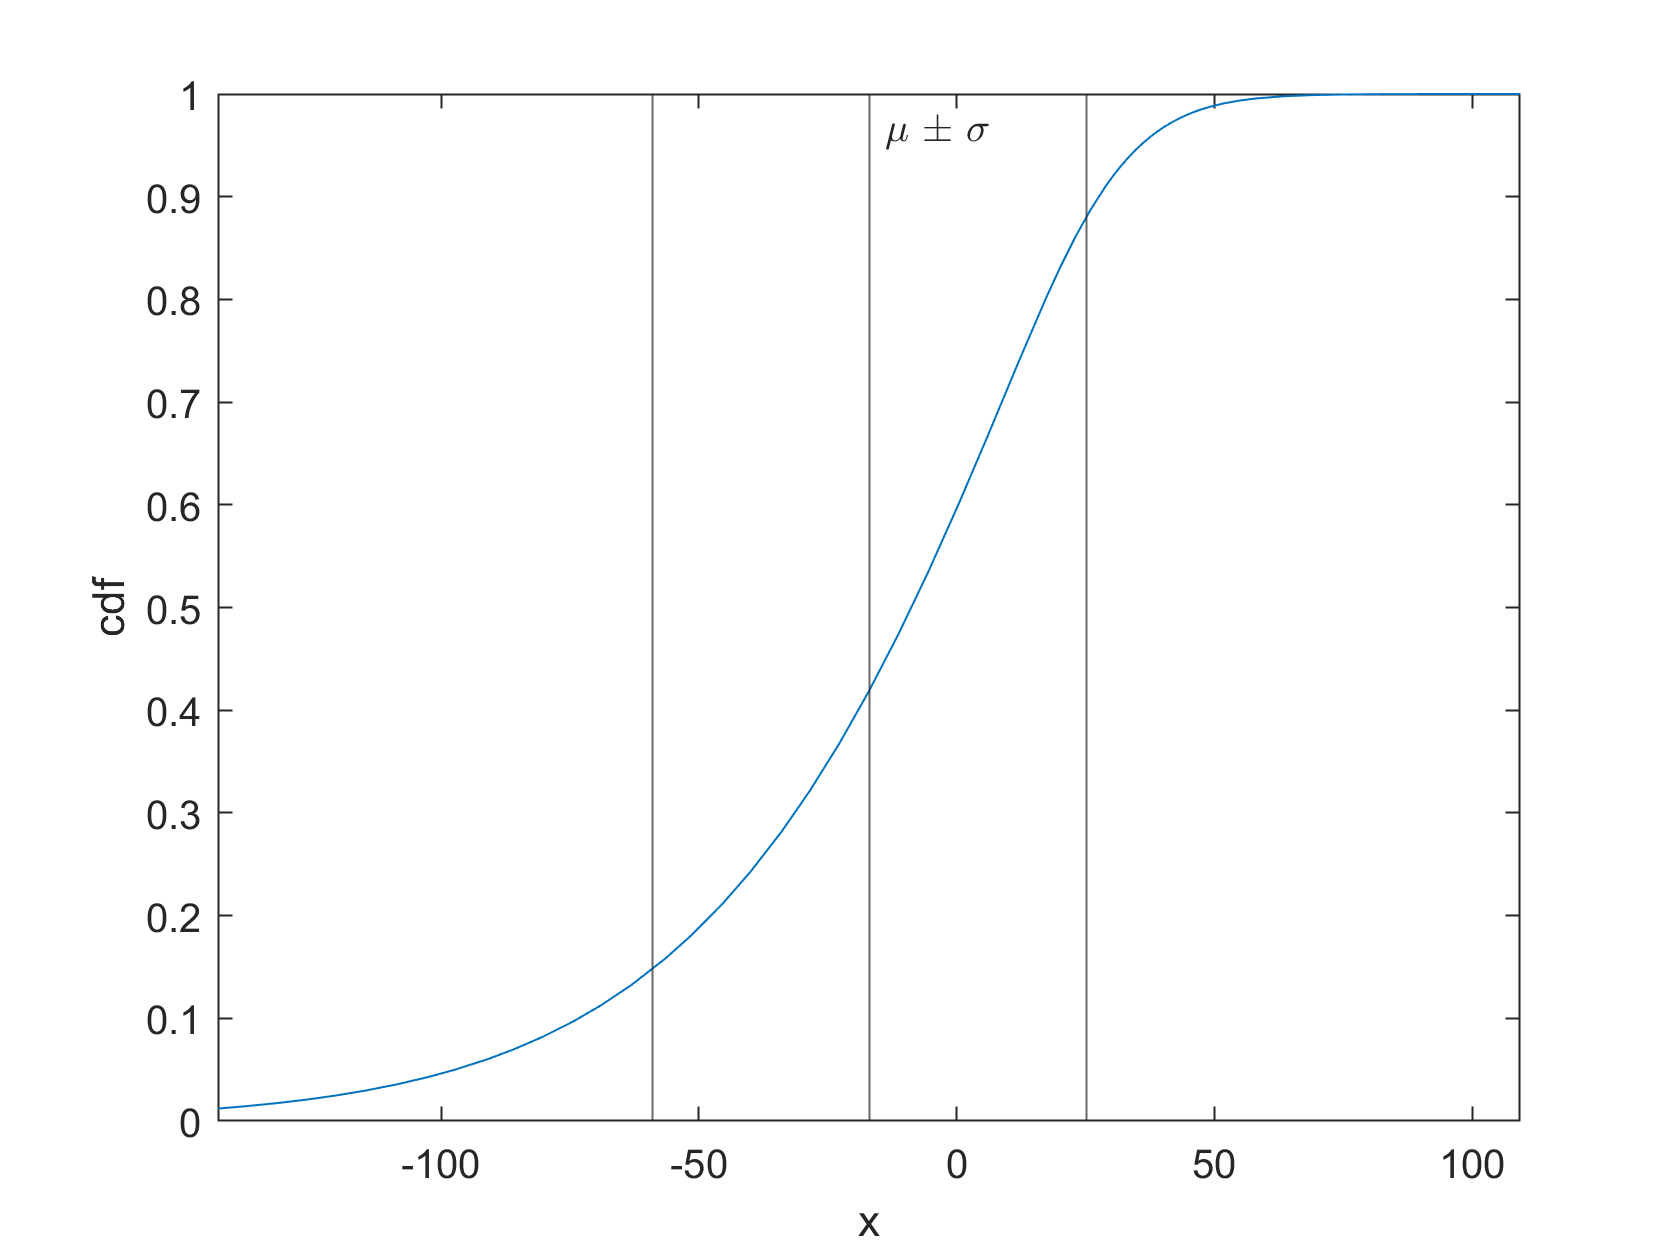

figure; fplot(@(x) gx2cdf(x,lambda,m,delta,sigma,c));
xline(mu,'-',{'\mu \pm \sigma'},'labelorientation','horizontal');
xline(mu-sqrt(v),'-'); xline(mu+sqrt(v),'-');
xlim([mu-3*sqrt(v),mu+3*sqrt(v)]); ylim([0 1]); xlabel x; ylabel 'cdf'

## Calculate inverse cdf

x=gx2inv([0.5 0.9],lambda,m,delta,sigma,c)

x =    -8.7657   27.5320


## Distribution of quadratic form of a normal variable

% normal parameters
mu=[1;2]; % mean
v=[2 1; 1 3]; % covariance matrix

$q(\mathbf{x})=(x_1+x_2)^2-x_1-1$` = [x1;x2]'*[1 1; 1 1]*[x1;x2] + [-1;0]'*[x1;x2] -1`

quad.q2=[1 1; 1 1];
quad.q1=[-1;0];
quad.q0=-1;

% get gx2 parameters corr. to this quadratic form
[lambda,m,delta,sigma,c]=gx2_params_norm_quad(mu,v,quad)

lambda = 7.0000

m = 1

delta = 1.1086

sigma = 0.8452

c = -0.7602


$$p(q(\mathbf{x})<3)$$


p=gx2cdf(3,lambda,m,delta,sigma,c)

p = 0.3351